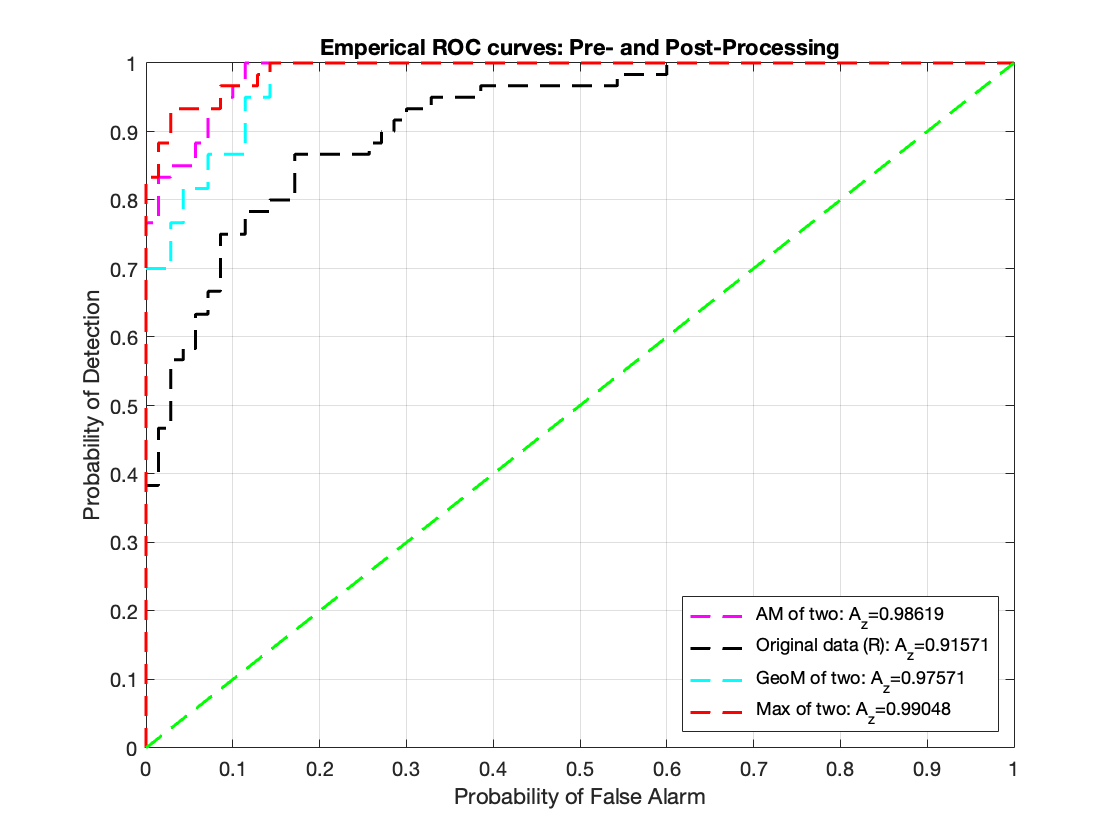

clear;
close all; clc
r = raylrnd(1:130) ;
r_Absent = r(1:70);
r_Present =  r(71:end);
r_Absent = r_Absent.';
r_Present = r_Present.';
a1 = 1:130;
b1 = 2;
g = gamrnd(a1,b1);
g_Absent = g(1:70);
g_Present = g(71:end);
g_Absent = g_Absent.';
g_Present = g_Present.';

n = length(r_Absent);
    for i = 1:n
        cc = r_Absent + g_Absent;
        b(i)=(cc(i))/2;
        AMeanA=b.';
    end
n1 = length(r_Present);
    for ii = 1:n1
        cc1 = r_Present + g_Present;
        b1(ii)=(cc1(ii))/2;
        AMeanP=b1.';
    end
n = length(r_Absent);
    for i = 1:n
        h = r_Absent .* g_Absent;
        p(i)=sqrt(h(i));
        GeoMeanA=p.';
    end
n1 = length(r_Present);
    for ii = 1:n1
        h1 = r_Present .* g_Present;
        p1(ii) = sqrt(h1(ii));
        GeoMeanP=p1.';
    end
n = length(r_Absent);
    for i = 1:n
        j = [r_Absent g_Absent];
        u(i) = max(j(i,:));
        MaxA=u.';
    end
n1 = length(r_Present);
    for ii = 1:n1
        j1 = [r_Present g_Present];
        u1(ii) = max(j1(ii,:));
        MaxP=u1.';
    end
xx = 0:0.25:1.2*max(AMeanA);
xx = xx.';
yy = 0:0.25:1.2*max(AMeanP);
yy = yy.';

N0 = length(AMeanA);
N1 = length(AMeanP);
dat = [];
dat1 = [];
dat2 = [];
dat(1:70) = AMeanA;
dat(71:130) = AMeanP;
dat1(1:70) = GeoMeanA;
dat1(71:130) = GeoMeanP;
dat2(1:70) = MaxA;
dat2(71:130) = MaxP;
dat = dat.';
dat1 = dat1.';
dat2 = dat2.';
resp = [zeros(N0,1);ones(N1,1)];
[pf0,pd0,T0,AUC0,OPTOCPT0] = perfcurve(resp,r,1);
[pf,pd,T,AUC,OPTOCPT] = perfcurve(resp,dat,1);
[pf1,pd1,T1,AUC1,OPTOCPT1] = perfcurve(resp,dat1,1);
[pf2,pd2,T2,AUC2,OPTOCPT2] = perfcurve(resp,dat2,1);
in_auc0 = AUC0;
in_auc = AUC;
in_auc1 = AUC1;
in_auc2 = AUC2;
figure
plot(pf,pd, 'm', 'LineStyle', '- -','LineWidth',1.5)
hold on;
plot(pf0,pd0, 'k', 'LineStyle', '- -','LineWidth',1.5)
plot(pf1,pd1, 'c', 'LineStyle', '- -','LineWidth',1.5)
plot(pf2,pd2, 'r', 'LineStyle', '- -','LineWidth',1.5)
x = [0,1];
y = [0,1];
plot(x,y, 'g', 'LineStyle', '- -', 'LineWidth',1.5)
grid on;
title('Emperical ROC curves: Pre- and Post-Processing')
xlabel('Probability of False Alarm' )
ylabel('Probability of Detection')
legend(['AM of two: A_z=', num2str(in_auc)] ,['Original data (R): A_z=', num2str(in_auc0)],['GeoM of two: A_z=', num2str(in_auc1)],['Max of two: A_z=', num2str(in_auc2)], 'Location', 'southeast')
hold off

%threshold matrix ppv and err rate
N0 = 70;
N1 = 60;
N = N0 + N1;

%orig 
fprintf("Original data (R)")

Original data (R)

thr0 = T0((pf0==OPTOCPT0(1))&(pd0==OPTOCPT0(2)))

thr0 = 66.0474


Q0 = r_Absent>thr0;
r_Nf = sum(Q0(:) == 1);
E0 = r_Present>thr0;
r_Nc= sum(E0(:) == 1);

PI0 = abs(mean(r_Absent)-mean(r_Present))/sqrt(var(r_Absent)+var(r_Present))

PI0 = 1.2626

ppv0 = r_Nc/(r_Nc+r_Nf)

ppv0 = 0.8095

errR0 = (r_Nf+(N1 - r_Nc))/N

errR0 = 0.1615

CM0 = [(N0-r_Nf), (N1-r_Nc); (r_Nf),(r_Nc)]

CM0 =     58     9
    12    51


TM0 = CM0 * [(1/N0),0;0,(1/N1)]

TM0 =     0.8286    0.1500
    0.1714    0.8500



%arith mean 
fprintf("Arith Mean")

Arith Mean

thr = T((pf==OPTOCPT(1))&(pd==OPTOCPT(2)))

thr = 98.2931


Q = AMeanA>thr;
AM_Nf = sum(Q(:) == 1);
E = AMeanP>thr;
AM_Nc= sum(E(:) == 1);

PI = abs(mean(AMeanA)-mean(AMeanP))/sqrt(var(AMeanA)+var(AMeanP))

PI = 2.0105

ppv = AM_Nc/(AM_Nc+AM_Nf)

ppv = 0.8806

errR = (AM_Nf+(N1 - AM_Nc))/N

errR = 0.0692

CM = [(N0-AM_Nf), (N1-AM_Nc); (AM_Nf),(AM_Nc)]

CM =     62     1
     8    59


TM = CM * [(1/N0),0;0,(1/N1)]

TM =     0.8857    0.0167
    0.1143    0.9833



%geo mean 
thr1 = T1((pf1==OPTOCPT1(1))&(pd1==OPTOCPT1(2)))

thr1 = 84.5498


fprintf("Geo Mean")

Geo Mean

Q1 = GeoMeanA>thr1;
GM_Nf = sum(Q1(:) == 1);
E1 = GeoMeanP>thr1;
GM_Nc= sum(E1(:) == 1);

PI1 = abs(mean(GeoMeanA)-mean(GeoMeanP))/sqrt(var(GeoMeanA)+var(GeoMeanP))

PI1 = 1.8269

ppv1 = GM_Nc/(GM_Nc+GM_Nf)

ppv1 = 0.8551

errR1 = (GM_Nf+(N1 - GM_Nc))/N

errR1 = 0.0846

CM1 = [(N0-GM_Nf), (N1-GM_Nc); (GM_Nf),(GM_Nc)]

CM1 =     60     1
    10    59


TM1 = CM1 * [(1/N0),0;0,(1/N1)]

TM1 =     0.8571    0.0167
    0.1429    0.9833



%max 
fprintf("MAX")

MAX

thr2 = T2((pf2==OPTOCPT2(1))&(pd2==OPTOCPT2(2)))

thr2 = 152.5753


Q2 = MaxA>thr2;
Max_Nf = sum(Q2(:) == 1);
E2 = MaxP>thr2;
Max_Nc= sum(E2(:) == 1);

PI2 = abs(mean(MaxA)-mean(MaxP))/sqrt(var(MaxA)+var(MaxP))

PI2 = 2.2138

ppv2 = Max_Nc/(Max_Nc+Max_Nf)

ppv2 = 0.9649

errR2 = (Max_Nf+(N1 - Max_Nc))/N

errR2 = 0.0538

CM2 = [(N0-Max_Nf), (N1-Max_Nc); (Max_Nf),(Max_Nc)]

CM2 =     68     5
     2    55


TM2 = CM2 * [(1/N0),0;0,(1/N1)]

TM2 =     0.9714    0.0833
    0.0286    0.9167


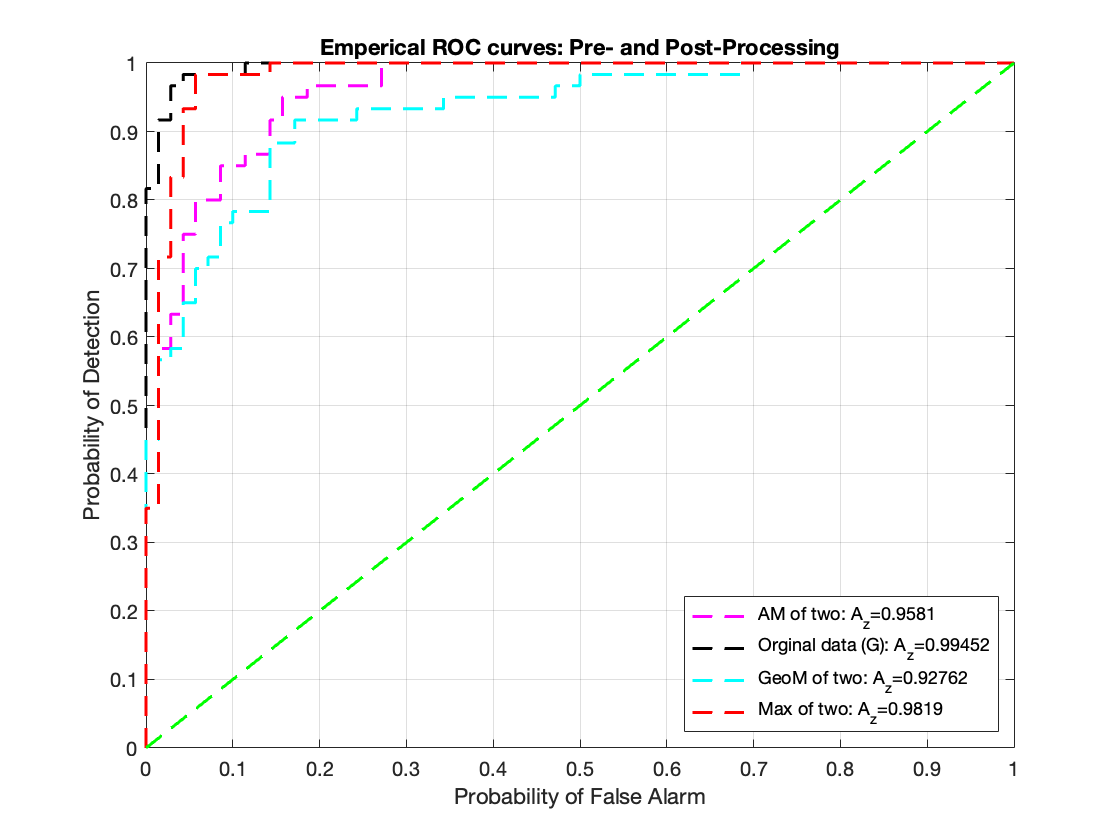

r = raylrnd(1:130) ;
r_Absent = r(1:70);
r_Present =  r(71:end);
r_Absent = r_Absent.';
r_Present = r_Present.';
a1 = 1:130;
b1 = 2;
g = gamrnd(a1,b1);
g_Absent = g(1:70);
g_Present = g(71:end);
g_Absent = g_Absent.';
g_Present = g_Present.';

n = length(r_Absent);
    for i = 1:n
        cc = r_Absent + g_Absent;
        b(i)=(cc(i))/2;
        AMeanA=b.';
    end
n1 = length(r_Present);
    for ii = 1:n1
        cc1 = r_Present + g_Present;
        b1(ii)=(cc1(ii))/2;
        AMeanP=b1.';
    end
n = length(r_Absent);
    for i = 1:n
        h = r_Absent .* g_Absent;
        p(i)=sqrt(h(i));
        GeoMeanA=p.';
    end
n1 = length(r_Present);
    for ii = 1:n1
        h1 = r_Present .* g_Present;
        p1(ii) = sqrt(h1(ii));
        GeoMeanP=p1.';
    end
n = length(r_Absent);
    for i = 1:n
        j = [r_Absent g_Absent];
        u(i) = max(j(i,:));
        MaxA=u.';
    end
n1 = length(r_Present);
    for ii = 1:n1
        j1 = [r_Present g_Present];
        u1(ii) = max(j1(ii,:));
        MaxP=u1.';
    end
xx = 0:0.25:1.2*max(AMeanA);
xx = xx.';
yy = 0:0.25:1.2*max(AMeanP);
yy = yy.';

N0 = length(AMeanA);
N1 = length(AMeanP);
dat = [];
dat1 = [];
dat2 = [];
dat(1:70) = AMeanA;
dat(71:130) = AMeanP;
dat1(1:70) = GeoMeanA;
dat1(71:130) = GeoMeanP;
dat2(1:70) = MaxA;
dat2(71:130) = MaxP;
dat = dat.';
dat1 = dat1.';
dat2 = dat2.';
resp = [zeros(N0,1);ones(N1,1)];
[pf,pd,T,AUC,OPTOCPT] = perfcurve(resp,dat,1);
[pf0,pd0,T0,AUC0,OPTOCPT0] = perfcurve(resp,g,1);
[pf1,pd1,T1,AUC1,OPTOCPT1] = perfcurve(resp,dat1,1);
[pf2,pd2,T2,AUC2,OPTOCPT2] = perfcurve(resp,dat2,1);
in_auc0 = AUC0;
in_auc = AUC;
in_auc1 = AUC1;
in_auc2 = AUC2;
figure
plot(pf,pd, 'm', 'LineStyle', '- -','LineWidth',1.5)
hold on;
plot(pf0,pd0, 'k', 'LineStyle', '- -','LineWidth',1.5)
plot(pf1,pd1, 'c', 'LineStyle', '- -','LineWidth',1.5)
plot(pf2,pd2, 'r', 'LineStyle', '- -','LineWidth',1.5)
x = [0,1];
y = [0,1];
plot(x,y, 'g', 'LineStyle', '- -','LineWidth',1.5)
grid on;
title('Emperical ROC curves: Pre- and Post-Processing')
xlabel('Probability of False Alarm' )
ylabel('Probability of Detection')
legend(['AM of two: A_z=', num2str(in_auc)] ,['Orginal data (G): A_z=', num2str(in_auc0)],['GeoM of two: A_z=', num2str(in_auc1)],['Max of two: A_z=', num2str(in_auc2)], 'Location', 'southeast')
hold off


%threshold matrix ppv and err rate
N0 = 70;
N1 = 60;
N = N0 + N1;

%orig 
fprintf("Original data (R)")

Original data (R)

thr0 = T0((pf0==OPTOCPT0(1))&(pd0==OPTOCPT0(2)))

thr0 = 137.7247


Q0 = r_Absent>thr0;
r_Nf = sum(Q0(:) == 1);
E0 = r_Present>thr0;
r_Nc= sum(E0(:) == 1);

PI0 = abs(mean(r_Absent)-mean(r_Present))/sqrt(var(r_Absent)+var(r_Present))

PI0 = 0.9781

ppv0 = r_Nc/(r_Nc+r_Nf)

ppv0 = 0.9032

errR0 = (r_Nf+(N1 - r_Nc))/N

errR0 = 0.2692

CM0 = [(N0-r_Nf), (N1-r_Nc); (r_Nf),(r_Nc)]

CM0 =     67    32
     3    28


TM0 = CM0 * [(1/N0),0;0,(1/N1)]

TM0 =     0.9571    0.5333
    0.0429    0.4667



%arith mean 
fprintf("Arith Mean")

Arith Mean

thr = T((pf==OPTOCPT(1))&(pd==OPTOCPT(2)))

thr = 97.1436


Q = AMeanA>thr;
AM_Nf = sum(Q(:) == 1);
E = AMeanP>thr;
AM_Nc= sum(E(:) == 1);

PI = abs(mean(AMeanA)-mean(AMeanP))/sqrt(var(AMeanA)+var(AMeanP))

PI = 1.6229

ppv = AM_Nc/(AM_Nc+AM_Nf)

ppv = 0.8358

errR = (AM_Nf+(N1 - AM_Nc))/N

errR = 0.1154

CM = [(N0-AM_Nf), (N1-AM_Nc); (AM_Nf),(AM_Nc)]

CM =     59     4
    11    56


TM = CM * [(1/N0),0;0,(1/N1)]

TM =     0.8429    0.0667
    0.1571    0.9333



%geo mean 
thr1 = T1((pf1==OPTOCPT1(1))&(pd1==OPTOCPT1(2)))

thr1 = 97.7424


fprintf("Geo Mean")

Geo Mean

Q1 = GeoMeanA>thr1;
GM_Nf = sum(Q1(:) == 1);
E1 = GeoMeanP>thr1;
GM_Nc= sum(E1(:) == 1);

PI1 = abs(mean(GeoMeanA)-mean(GeoMeanP))/sqrt(var(GeoMeanA)+var(GeoMeanP))

PI1 = 1.4123

ppv1 = GM_Nc/(GM_Nc+GM_Nf)

ppv1 = 0.8387

errR1 = (GM_Nf+(N1 - GM_Nc))/N

errR1 = 0.1385

CM1 = [(N0-GM_Nf), (N1-GM_Nc); (GM_Nf),(GM_Nc)]

CM1 =     60     8
    10    52


TM1 = CM1 * [(1/N0),0;0,(1/N1)]

TM1 =     0.8571    0.1333
    0.1429    0.8667



%max 
fprintf("MAX")

MAX

thr2 = T2((pf2==OPTOCPT2(1))&(pd2==OPTOCPT2(2)))

thr2 = 137.7247


Q2 = MaxA>thr2;
Max_Nf = sum(Q2(:) == 1);
E2 = MaxP>thr2;
Max_Nc= sum(E2(:) == 1);

PI2 = abs(mean(MaxA)-mean(MaxP))/sqrt(var(MaxA)+var(MaxP))

PI2 = 1.9078

ppv2 = Max_Nc/(Max_Nc+Max_Nf)

ppv2 = 0.9355

errR2 = (Max_Nf+(N1 - Max_Nc))/N

errR2 = 0.0462

CM2 = [(N0-Max_Nf), (N1-Max_Nc); (Max_Nf),(Max_Nc)]

CM2 =     66     2
     4    58


TM2 = CM2 * [(1/N0),0;0,(1/N1)]

TM2 =     0.9429    0.0333
    0.0571    0.9667
